# Implicit Deep Learning on forest fire dataset

clear all;
load([pwd,'/datasets/processed_data_fireforest'])
[n, m] = size(U);
permutation = randperm(m);
% permute the data using this permutation vector
Y = Y(permutation); Y_train = Y(1:floor(3*m/4)); Y_test = Y(ceil(3*m/4):m);
U = U(:,permutation); U_train = U(:,1:floor(3*m/4)); U_test = U(:,ceil(3*m/4):m);
m_train = size(Y_train,2); m_test = size(Y_test,2);
clear permutation;
disp(['deviation of Y_test: ', num2str((1/sqrt(m_test)*norm(Y_test)))])

deviation of Y_test: 1.3726


## Simplest model, mean

prediction = mean(Y_train);
disp(['Train RMSE of fire area (log): ', num2str(1/sqrt(m_train)*norm(Y_train-prediction)) ]);

Train RMSE of fire area (log): 1.4058


disp(['Test RMSE of fire area (log): ', num2str(1/sqrt(m_test)*norm(Y_test-prediction)) ]);

Test RMSE of fire area (log): 1.3709


## Start with linear regression using cvx with Lasso

lasso_coeff = 4;
cvx_begin quiet
variable A(1,n)
variable b(1)
minimize(norm(Y_train-A*U_train-b,2)+lasso_coeff*norm(A,2))
cvx_end
A = round(A,6); b=round(b,6);
disp(['Train RMSE of fire area (log): ',num2str((1/sqrt(m_train))*(norm(Y_train-A*U_train-b,"fro")))]);

Train RMSE of fire area (log): 1.4058


disp(['Train RMSE of fire area (log): ',num2str((1/sqrt(m_test))*(norm(Y_test-A*U_test-b,"fro")))]);

Train RMSE of fire area (log): 1.3709


we can see that this does not improve the quality of the model, showing that this is a hard regression problem. Playing with the lasso hyperparameter actually shows that taking $A=0$ is actually the best choice, going back to the mean model.

## Feedforward Neural Network model (Deep Learning)

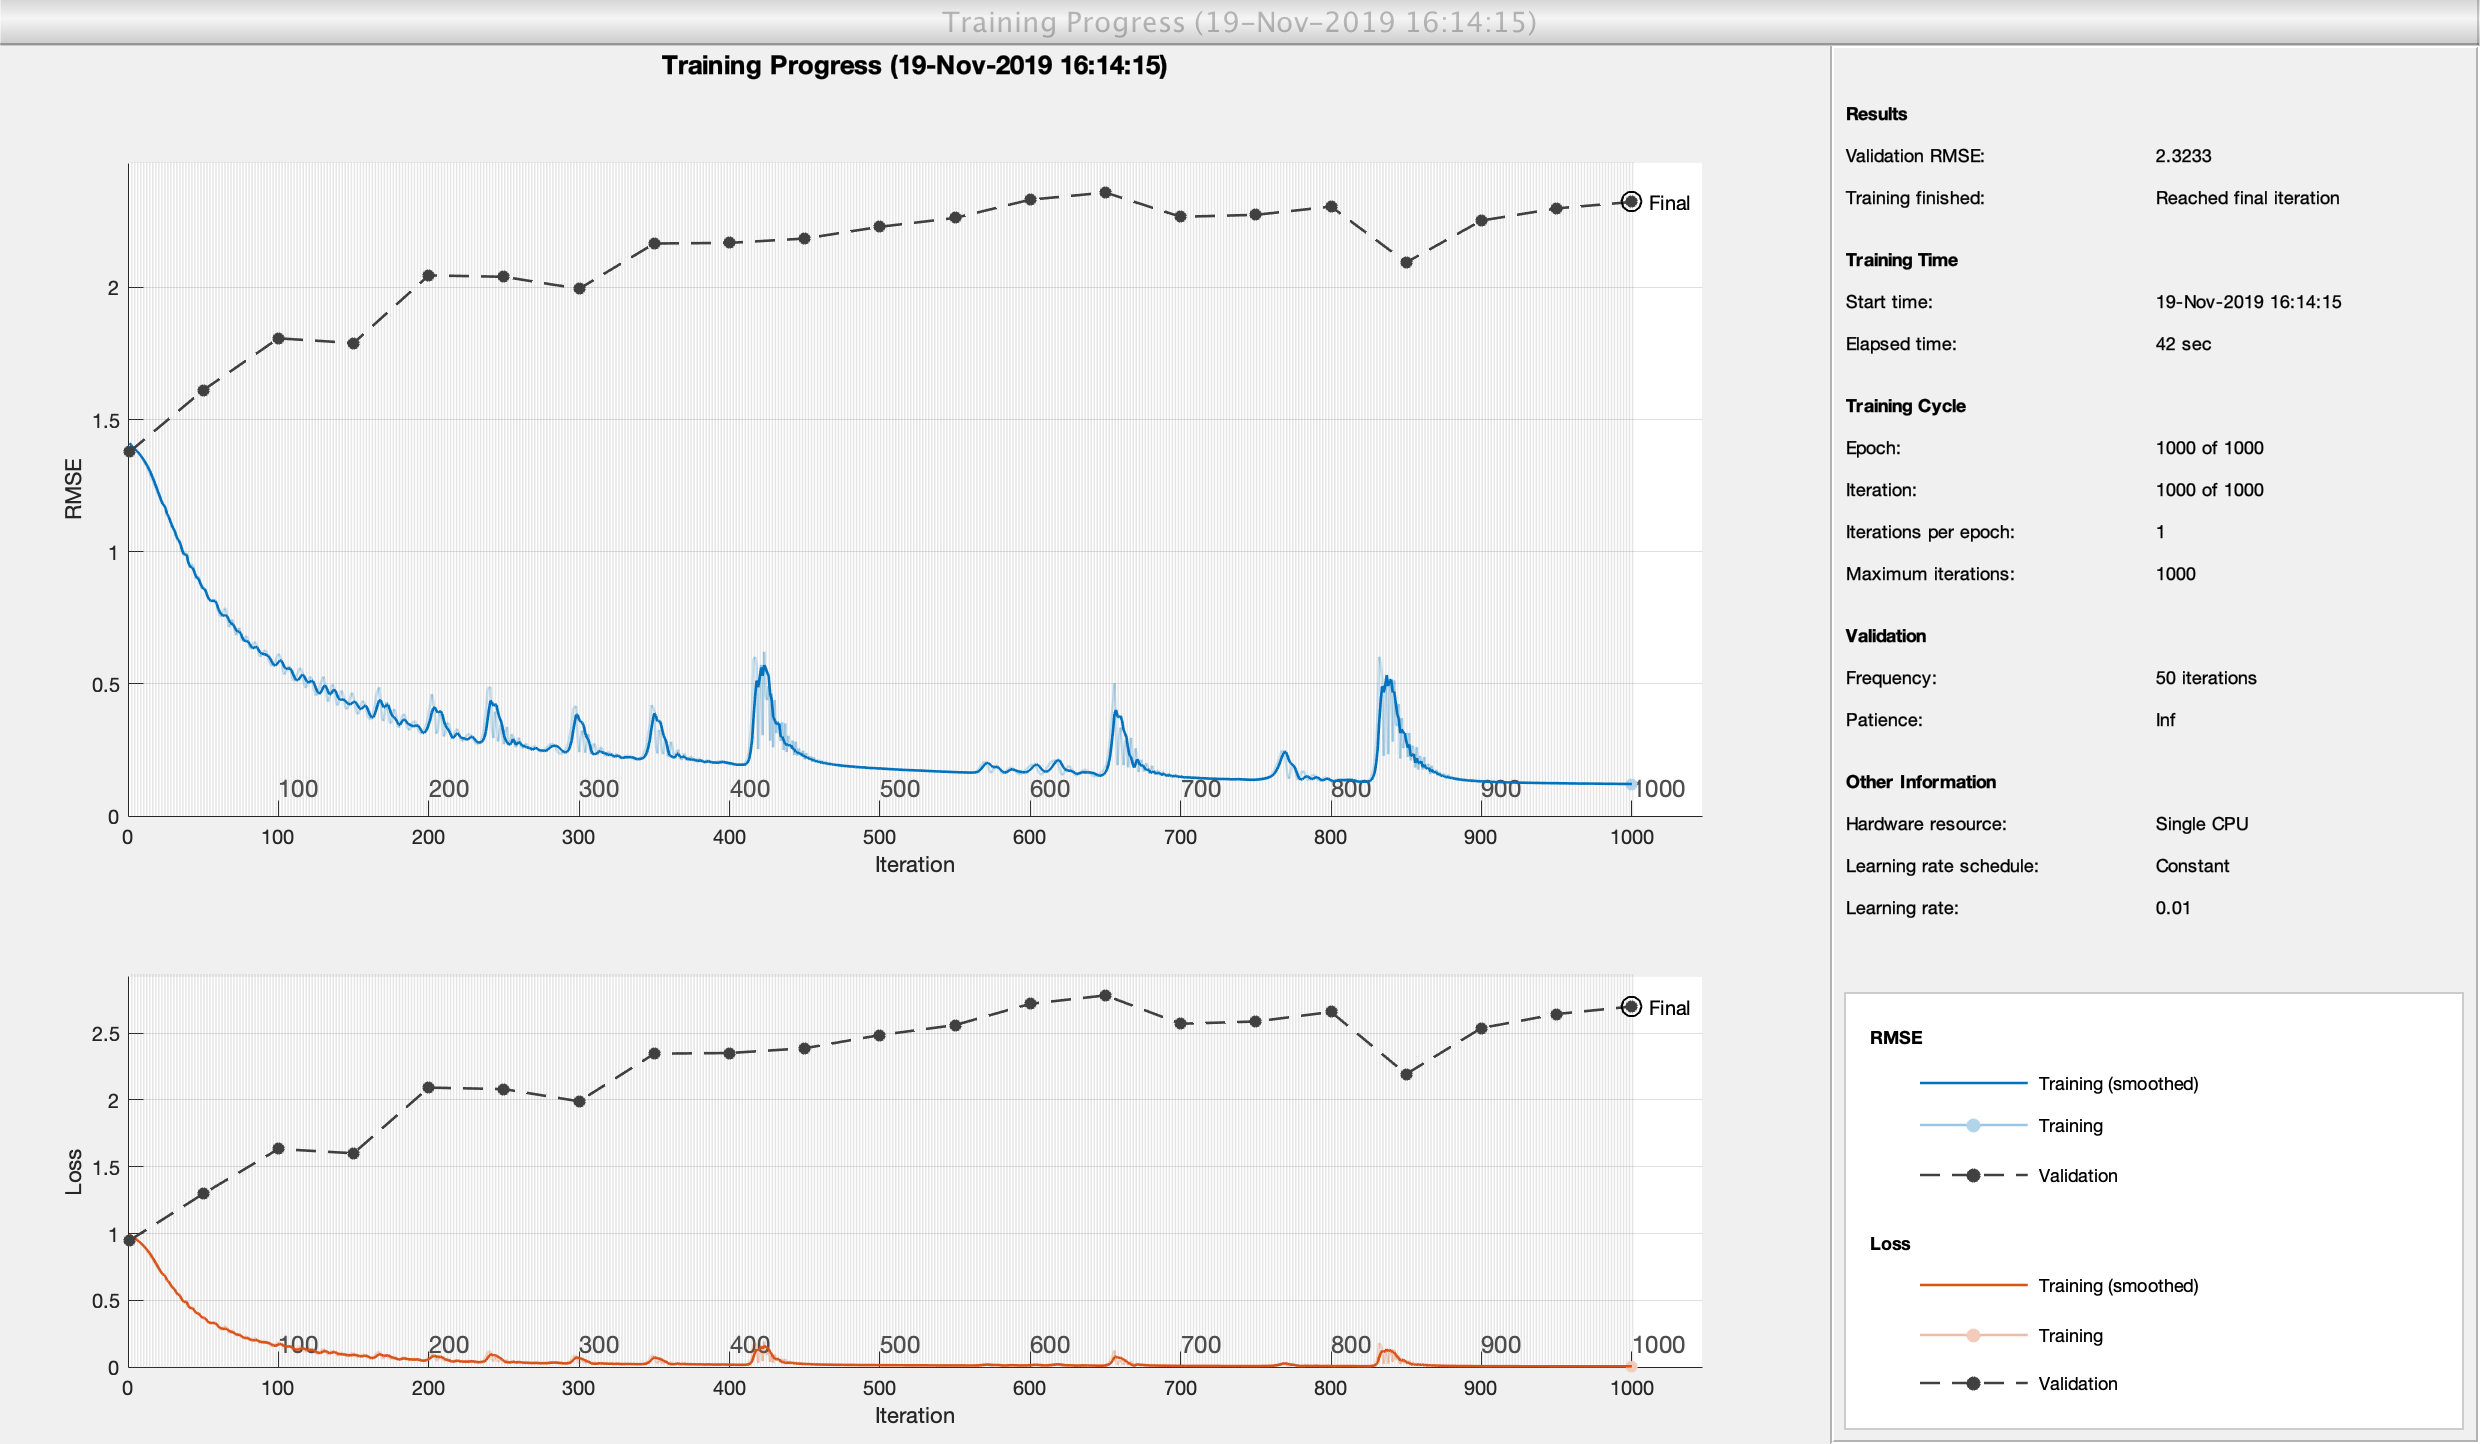

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |         1.41 |         1.38 |       0.9946 |       0.9490 |          0.0100 |
|      50 |          50 |       00:00:03 |         0.86 |         1.61 |       0.3708 |       1.2976 |          0.0100 |
|     100 |         100 |       00:00:05 |         0.61 |         1.81 |       0.1885 |       1.6331 |          0.0100 |
|     150 |         150 |       00:00:07 |         0.45 |         1.79 |       0.1011 |       1.6009 |          0.0100 |
|     20

layers = [
    sequenceInputLayer(n)
    fullyConnectedLayer(20)
    reluLayer 
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(20)
    reluLayer
    fullyConnectedLayer(5)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];
max_epochs= 10^3;
validationFrequency = ceil(max_epochs/20);
options = trainingOptions('adam','MaxEpochs',max_epochs,'MiniBatchSize',m_train,'InitialLearnRate',10^-2, ...
    'ValidationData',{U_test,Y_test}, 'ValidationFrequency',validationFrequency,'Plots','training-progress');
net = trainNetwork(U_train,Y_train,layers,options);

% Sanity check
Y_predicted = predict(net,U_test); 
Y_train_predicted = predict(net,U_train);
disp(['Train RMSE of fire area (log): ',num2str((1/sqrt(m_train))*(norm(Y_train-Y_train_predicted,"fro")))]);

Train RMSE of fire area (log): 0.26502


disp(['Test RMSE of fire area (log): ',num2str((1/sqrt(m_test))*(norm(Y_test-Y_predicted,"fro")))]);

Test RMSE of fire area (log): 1.6473
